# CLASSIFICADOR D'HISTOGRAMES

User_root      = '/Users/pau.diport.i/Documents/MATLAB/PIV/PROG';
Data_root      = '/database/';
Input_filename = 'input.txt';
Output_filename= 'output.txt';
Num_images     = 20;
Candidates     = 10;

M = 2000;
Num_GoPs = M / 4;

## MATRIU DE GoPs

matriu_images_indiv = zeros(M, 128); 

for g = 0:Num_GoPs-1
    hist_bloc = zeros(4, 256);
    for k = 0:3
        ruta = fullfile(User_root, Data_root, sprintf("ukbench%05d.jpg", g*4 + k));
        img = imread(ruta);
        
        hsv = rgb2hsv(img);
        
        % Quantització robusta de l'espai HSV (MPEG-7 coherent)
        H = min(floor(hsv(:,:,1) * 16), 15);
        S = min(floor(hsv(:,:,2) * 4), 3);
        V = min(floor(hsv(:,:,3) * 4), 3);
        idx = H*16 + S*4 + V + 1;
        
        h = accumarray(idx(:), 1, [256 1])';
        h_norm = h / sum(h);
        hist_bloc(k+1, :) = h_norm; 
        
        % Guardem el descriptor individual de la imatge per a la segona etapa
        [a_indiv, ~] = haart(h_norm, 1);
        matriu_images_indiv(g*4 + k + 1, :) = a_indiv(:)';
    end
    
    % --- 1. INTERSECCIÓ (Mínim) ---
    gop_int = min(hist_bloc, [], 1);
    gop_int = gop_int / sum(gop_int); 
    [a_i, ~] = haart(gop_int, 1);     
    matriu_gops_int(g+1, :) = a_i(:)';

    % --- 2. MITJANA (Average) ---
    gop_avg = mean(hist_bloc, 1);
    [a_a, ~] = haart(gop_avg, 1);
    matriu_gops_avg(g+1, :) = a_a(:)';

    % --- 3. MEDIANA (Median) ---
    gop_med = median(hist_bloc, 1);
    gop_med = gop_med / sum(gop_med); 
    [a_m, ~] = haart(gop_med, 1);
    matriu_gops_med(g+1, :) = a_m(:)';
end

## PROCESSAMENT DE QUERIES

fileID = fopen(Input_filename, 'r');
imageNames = textscan(fileID, '%s');
fclose(fileID);
noms_inputs = string(imageNames{1}(1:Num_images));

matriu_inputs = zeros(Num_images, 128);
for i = 1:Num_images
    ruta = fullfile(User_root, Data_root, noms_inputs(i));
    img = imread(ruta);
    hsv = rgb2hsv(img);
    
    % Quantització idèntica a la BD per garantir distància 0 en imatges idèntiques
    H = min(floor(hsv(:,:,1) * 16), 15); 
    S = min(floor(hsv(:,:,2) * 4), 3); 
    V = min(floor(hsv(:,:,3) * 4), 3);
    idx = H*16 + S*4 + V + 1;
    
    h = accumarray(idx(:), 1, [256 1])';
    h_norm = h / sum(h);
    
    [a, ~] = haart(h_norm, 1);
    matriu_inputs(i, :) = a(:)'; 
end

## DISTÀNCIES

metodes_gops = {matriu_gops_int, matriu_gops_avg, matriu_gops_med};
noms_metodes = ["Interseccio", "Average", "Median"];

% Matriu final on guardarem els indexs de les imatges candidates (en rang 1 a 2000 per MATLAB)
idx_candidats = zeros(3, 2, Num_images, Candidates);

for m = 1:3
    matriu_actual = metodes_gops{m};
    
    for i = 1:Num_images
        h_query = matriu_inputs(i, :);
        
        % Càlcul de distàncies de la query a cada un dels 500 GoPs
        dist_L1 = sum(abs(matriu_actual - h_query), 2)';
        dist_L2 = sqrt(sum((matriu_actual - h_query).^2, 2))';
        
        [~, ord_L1] = sort(dist_L1, 'ascend');
        [~, ord_L2] = sort(dist_L2, 'ascend');
        
        dist_tipus = {ord_L1, ord_L2};
        
        for d = 1:2
            gops_ordenats = dist_tipus{d};
            llista_candidats_img = [];
            
            % Anem agafant els millors GoPs un a un i afegim les seves 4 imatges reals
            % fins que tinguem com a mínim els 10 candidats requerits.
            for g_idx = 1:length(gops_ordenats)
                id_gop_real = gops_ordenats(g_idx) - 1; % Passem a 0-based (Ex: GoP 0 a 499)
                
                % Les 4 imatges reals d'aquest GoP (en format 0-based) són:
                img0 = id_gop_real * 4;
                img1 = id_gop_real * 4 + 1;
                img2 = id_gop_real * 4 + 2;
                img3 = id_gop_real * 4 + 3;
                
                % Convertim aquests IDs reals a índexs de MATLAB (1-based) sumant 1
                % Imatges candidates en format MATLAB:
                llista_candidats_img = [llista_candidats_img, (img0+1), (img1+1), (img2+1), (img3+1)];
                
                % Si ja hem omplert prou imatges per cobrir els "Candidates" (10), parem
                if length(llista_candidats_img) >= Candidates
                    break;
                end
            end
            
            % Guardem exactament els primers 10 candidats filtrats i ben indexats
            idx_candidats(m, d, i, :) = llista_candidats_img(1:Candidates);
        end
    end
end

## AVALUACIÓ I GENERACIÓ DE GRÀFIQUES

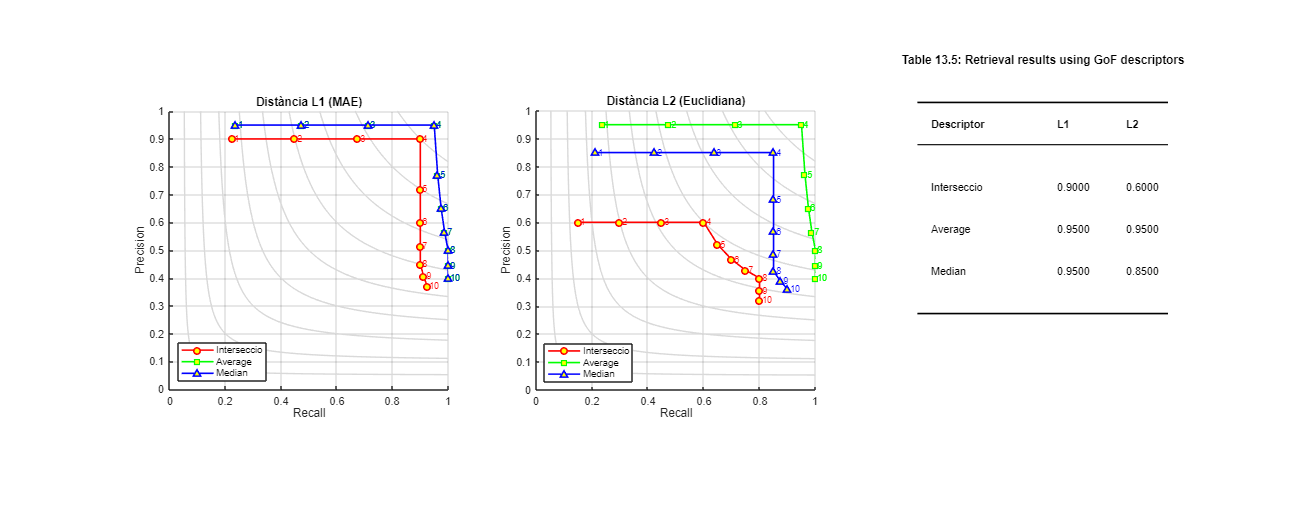

res_mean_p = cell(3, 2); 
res_mean_r = cell(3, 2); 
res_max_f  = zeros(3, 2); 

for m = 1:3
    for d = 1:2
        prec_mat = zeros(Num_images, Candidates);
        rec_mat  = zeros(Num_images, Candidates);
        
        for i = 1:Num_images
            % Extraiem el número real de la query des del seu nom (Ex: "ukbench01701.jpg" -> 1701)
            id_q_real = str2double(regexp(noms_inputs(i), '\d+', 'match'));
            grup_q_real = floor(id_q_real / 4);
            
            encerts = 0;
            for j = 1:Candidates
                % idx_candidats conté índexs 1-based de MATLAB (Ex: 1702 significa imatge ukbench01701)
                idx_matlab = idx_candidats(m, d, i, j);
                id_img_real = idx_matlab - 1; % Passem a ID real de disc (0 a 1999)
                
                grup_candidat_real = floor(id_img_real / 4);
                
                % Si coincideixen els grups de veritat, és un encert acadèmic complet
                if grup_candidat_real == grup_q_real
                    encerts = encerts + 1;
                end
                
                prec_mat(i, j) = encerts / j;
                rec_mat(i, j) = encerts / 4; % Hi ha exactament 4 imatges bones a tot el món pel grup
            end
        end
        
        res_mean_p{m, d} = mean(prec_mat, 1);
        res_mean_r{m, d} = mean(rec_mat, 1);
        
        % Càlcul de l'F-score evitant divisions per zero
        f_vec = (2 .* res_mean_p{m, d} .* res_mean_r{m, d}) ./ (res_mean_p{m, d} + res_mean_r{m, d});
        f_vec(isnan(f_vec)) = 0;
        res_max_f(m, d) = max(f_vec);
    end
end

% --- RENDERITZAT VISUAL DE FIGURES (Igual que el teu codi base de disseny) ---
fig = figure('Name', 'Avaluació SCD GoP', 'Units', 'normalized', 'Position', [0.1, 0.1, 0.85, 0.6], 'Color', 'w');
[Rg, Pg] = meshgrid(linspace(0.001, 1, 100), linspace(0.001, 1, 100));
Fg = (2 .* Pg .* Rg) ./ (Pg + Rg);
cls = ['r', 'g', 'b']; 
marcadors = ['o', 's', '^'];
titols_dist = ["Distància L1 (MAE)", "Distància L2 (Euclidiana)"];

for d = 1:2
    ax = subplot(1, 3, d); hold on; grid on; axis square;
    contour(Rg, Pg, Fg, 0.1:0.1:0.9, 'Color', [0.85 0.85 0.85], 'HandleVisibility', 'off');
    for m = 1:3
        plot(res_mean_r{m, d}, res_mean_p{m, d}, ['-', marcadors(m), cls(m)], 'LineWidth', 1.5, ...
            'MarkerFaceColor', 'y', 'DisplayName', noms_metodes(m));
        for k = 1:Candidates
            text(res_mean_r{m, d}(k), res_mean_p{m, d}(k), sprintf(' %d', k), 'FontSize', 8, 'Color', cls(m));
        end
    end
    title(titols_dist(d), 'FontWeight', 'bold'); xlabel('Recall'); ylabel('Precision');
    xlim([0 1]); ylim([0 1]); legend('Location', 'southwest', 'FontSize', 9);
end

% Subplot 3: Taula de resultats acadèmica
ax_table = subplot(1, 3, 3); hold on; axis off; xlim([0 1]); ylim([0 1]);
text(0.5, 0.95, 'Table 13.5: Retrieval results using GoF descriptors', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'FontSize', 11);
plot([0.05, 0.95], [0.85, 0.85], 'k-', 'LineWidth', 1.5);
plot([0.05, 0.95], [0.75, 0.75], 'k-', 'LineWidth', 1);
plot([0.05, 0.95], [0.35, 0.35], 'k-', 'LineWidth', 1.5);
text(0.10, 0.80, 'Descriptor', 'FontWeight', 'bold', 'FontSize', 10);
text(0.55, 0.80, 'L1', 'FontWeight', 'bold', 'FontSize', 10);
text(0.80, 0.80, 'L2', 'FontWeight', 'bold', 'FontSize', 10);
y_pos = [0.65, 0.55, 0.45];
for m = 1:3
    text(0.10, y_pos(m), noms_metodes(m), 'FontSize', 10);
    text(0.55, y_pos(m), sprintf('%.4f', res_max_f(m, 1)), 'FontSize', 10);
    text(0.80, y_pos(m), sprintf('%.4f', res_max_f(m, 2)), 'FontSize', 10);
end
hold off;

## COST COMPUTACIONAL

tic;
% a) Extracció de característiques de la query
ruta_prova = fullfile(User_root, Data_root, noms_inputs(1));
img_prova = imread(ruta_prova);
hsv_prova = rgb2hsv(img_prova);
H_p = min(floor(hsv_prova(:,:,1) * 16), 15); 
S_p = min(floor(hsv_prova(:,:,2) * 4), 3); 
V_p = min(floor(hsv_prova(:,:,3) * 4), 3);
idx_p = H_p*16 + S_p*4 + V_p + 1;
h_p = accumarray(idx_p(:), 1, [256 1])';
h_norm_p = h_p / sum(h_p);
[a_p, ~] = haart(h_norm_p, 1);

% b) Cerca en dues etapes (Cas base: L1 i Average)
dist_prova_L1 = sum(abs(matriu_gops_avg - a_p(:)'), 2)';
[~, ord_prova_gops] = sort(dist_prova_L1, 'ascend');

% Filtre de refinament individual real
top_gops_p = ord_prova_gops(1:5);
imatges_candidates_p = [];
for tg = top_gops_p
    imatges_candidates_p = [imatges_candidates_p, ((tg-1)*4 + 1 : (tg-1)*4 + 4)];
end
descriptors_indiv_p = matriu_images_indiv(imatges_candidates_p, :);
dist_indiv_p = sum(abs(descriptors_indiv_p - a_p(:)'), 2);
[~, ~] = sort(dist_indiv_p, 'ascend');

temps_classificacio = toc;

% Temps de referència Benchmark de MATLAB
tic;
fft(rand(1024*1024, 1));
temps_benchmark = toc;

% Resultats finals per consola
fprintf('Temps Class/Imatge optimitzat (al teu PC): %.4f segons\n', temps_classificacio);

Temps Class/Imatge optimitzat (al teu PC): 0.0326 segons


fprintf('Temps de Ref. Benchmark (FFT Matlab): %.4f segons\n', temps_benchmark);

Temps de Ref. Benchmark (FFT Matlab): 0.0209 segons


## BIBLIOGRAFIA

- Funció haart i la seva aplicació: [https://es.mathworks.com/help/wavelet/ref/haart.html](https://es.mathworks.com/help/wavelet/ref/haart.html)